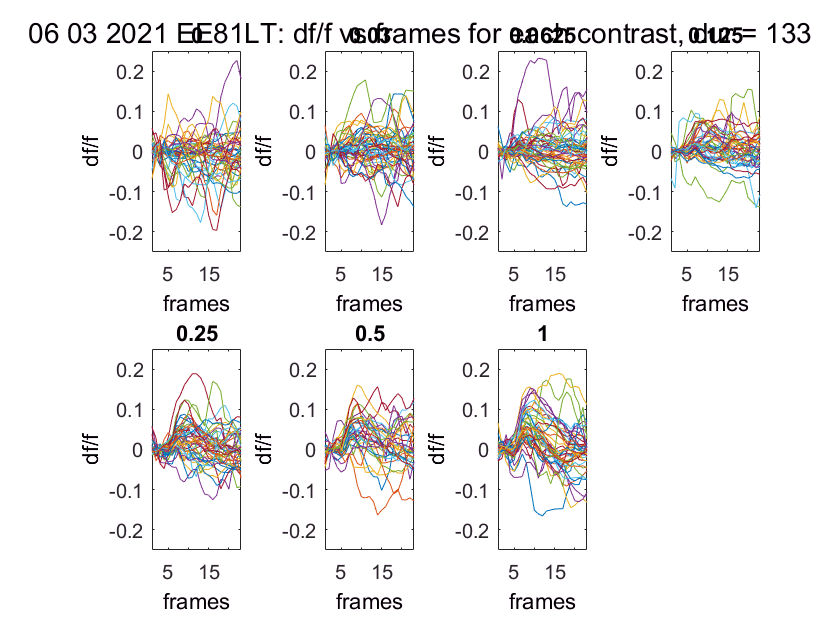

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% V1
% D = 133 ms
% all CONs

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for each contrast, dur = 133'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
% for i = 1:length(xPickedPts) % for each point
for i = 1
    
    for d = 4
        
        for c = 1:length(uniqueContrasts)
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
            % getting TRIAL VECTOR
            clear onePtAllFramesOneTrial % make new var for each trial
            % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            % plot one baseline corrected trace at a time
            subplot(2,4,c) % make a subplot
            plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
            title(uniqueContrasts(c))
                
            hold on % hold for next trial
                
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.25 0.25]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        end % end c loop
        
    end % end d loop
       
end % end i loop

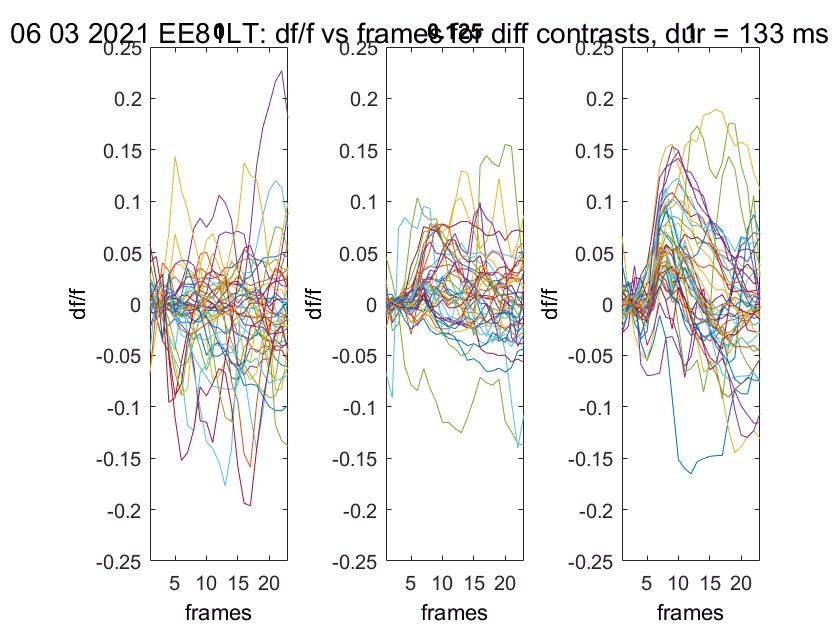

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% V1
% D = 133 ms
% C = 0.125

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for diff contrasts, dur = 133 ms'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
% for i = 1:length(xPickedPts) % for each point
for i = 1
    
    for d = 4
        
        loopCounter = 1;
        
        for c = [1 4 7]
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
            % getting TRIAL VECTOR
            clear onePtAllFramesOneTrial % make new var for each trial
            % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            subplot(1,3,loopCounter)
            plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
            title(uniqueContrasts(c))
                
            hold on % hold for next trial
                
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.25 0.25]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        loopCounter = loopCounter + 1;
        
        end % end c loop
        
    end % end d loop
       
end % end i loop

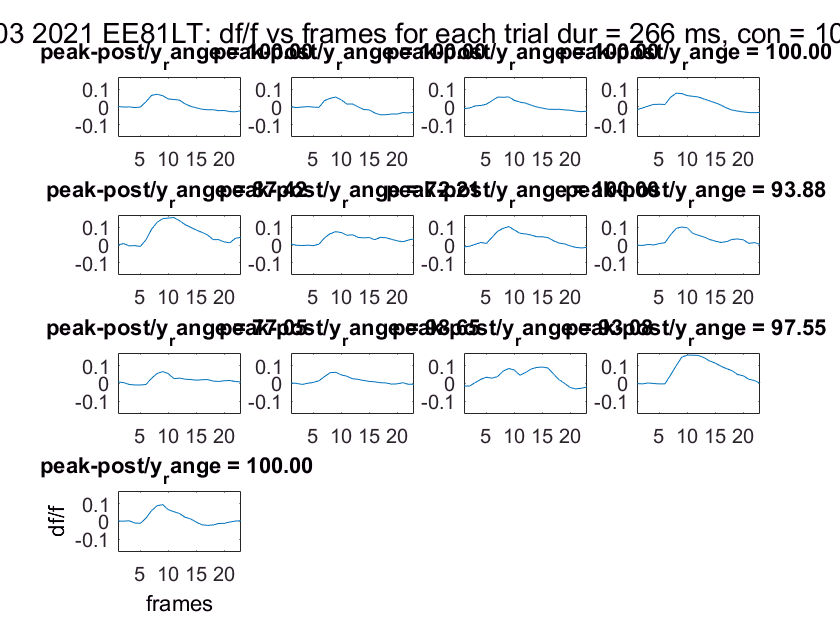

% each trial trace on it's own plot

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% V1
% D = 133 ms
% C = 0.125

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for each trial dur = 266 ms, con = 100%'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
% for i = 1:length(xPickedPts) % for each point
for i = 1
    
    for d = 5 % 266 ms
        
        loopCounter = 1;
        
        for c = 7 % 100%
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
                for tr = 1:size(onePtAllFramesAndTrials,1)/3 % 1st dim is trials, 2nd is frames
        
                % getting TRIAL VECTOR
                clear onePtAllFramesOneTrial % make new var for each trial
                % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            % roughly, sq
            % there's 47 trials
            % onePtAllFramesAndTrials is trials x frames
            numTrials =  size(onePtAllFramesAndTrials,1); % number of trials
            
             % max of peak frames (stim onset) minus min of all frames after frame 12 (end of peak response reigon)
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end));
            
            
            y_range = max(onePtAllFramesOneTrialMinusMeanBase)-min(onePtAllFramesOneTrialMinusMeanBase);
            peak2postNorm = peak2post/y_range;
            peak2postDivRangeMult100Percent = peak2postNorm*100;
            
            maxOfPeakFrames =  max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx));
            
            
            subplot(round(sqrt(size(onePtAllFramesAndTrials,1)/4))+1,round(sqrt(size(onePtAllFramesAndTrials,1)/4))+1,loopCounter) % put loop counter at end of tr loop now, so each trial has own subplot
        
            plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
            % title(uniqueContrasts(c))
            title(sprintf('max(peak)-min(post) = %0.002f %',peak2post))
            
            ylim([-0.17 0.17]) 
        xlim([1 length(x_axis)])
%         ylabel('df/f')
%         xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
                
            % hold on % don't hold for next trial - plot each trial on own subplot
                
            loopCounter = loopCounter + 1;
            
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.17 0.17]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        end % end c loop
        
    end % end d loop
       
end % end i loop

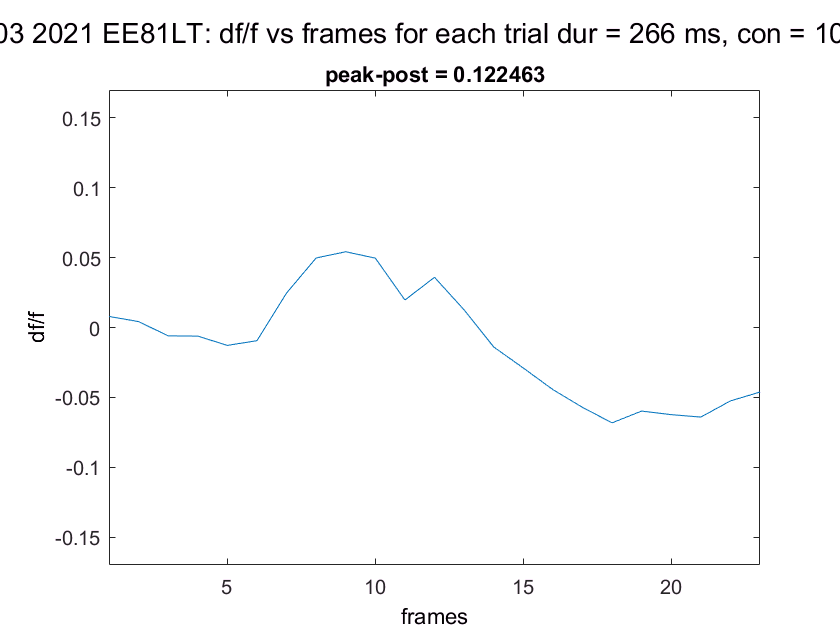

peak2post =       0.12246


% SLOPE for 1 example trial
% each trial trace on it's own plot

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% V1
% D = 133 ms
% C = 0.125

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for each trial dur = 266 ms, con = 100%'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
% for i = 1:length(xPickedPts) % for each point
for i = 1
    
    for d = 5 % 266 ms
        
        loopCounter = 1;
        
        for c = 7 % 100%
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            for tr = 25
            % for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
            % getting TRIAL VECTOR
            clear onePtAllFramesOneTrial % make new var for each trial
            % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            % roughly, sq
            % there's 47 trials
            % onePtAllFramesAndTrials is trials x frames
            numTrials =  size(onePtAllFramesAndTrials,1); % number of trials
         
            % max of peak frames (stim onset) minus min of all frames after frame 12 (end of peak response reigon)
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end)) 
            % denominator = length(x_axis) % num of frames/time
            %slope = numerator/denominator
            
%             clear stderr
%             stderr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthDthTrials)); % sum trials, not length
            
            % subplot(round((sqrt(numTrials)))+1,round((sqrt(numTrials)))+1,loopCounter) % put loop counter at end of tr loop now, so each trial has own subplot
            plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
            % title(uniqueContrasts(c))
            title(sprintf('peak-post = %f',peak2post))
            
            ylim([-0.17 0.17]) 
            xlim([1 length(x_axis)])
%          ylabel('df/f')
%          xlabel('frames')
            
           ax = gca;
           x.XTick = [1:1:length(x_axis)];
                
           % hold on % don't hold for next trial - plot each trial on own subplot
                
            loopCounter = loopCounter + 1;
            
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.17 0.17]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        end % end c loop
        
    end % end d loop
       
end % end i loop